# Load occupancy map

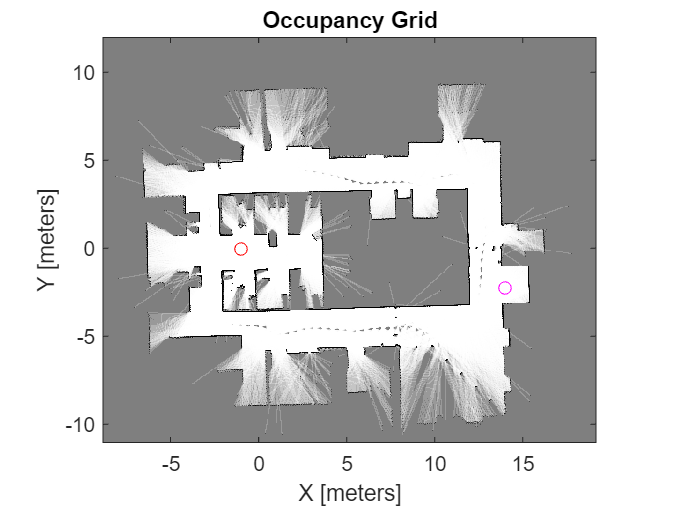

load("office_area_gridmap.mat","occGrid")
show(occGrid)

% Set start and goal poses.
start = [-1.0,0.0,-pi];
goal = [14,-2.25,0];

% Show start and goal positions of robot.
hold on
plot(start(1),start(2),'ro')
plot(goal(1),goal(2),'mo')

## define state space

bounds = [occGrid.XWorldLimits; occGrid.YWorldLimits; [-pi pi]];

ss = stateSpaceDubins(bounds);
ss.MinTurningRadius = 0.4;

## plan the path

stateValidator = validatorOccupancyMap(ss); 
stateValidator.Map = occGrid;
stateValidator.ValidationDistance = 0.05;

planner = plannerRRT(ss,stateValidator);
planner.MaxConnectionDistance = 2.0;
planner.MaxIterations = 30000;
rng default

[pthObj, solnInfo] = plan(planner,start,goal);

## plot the path

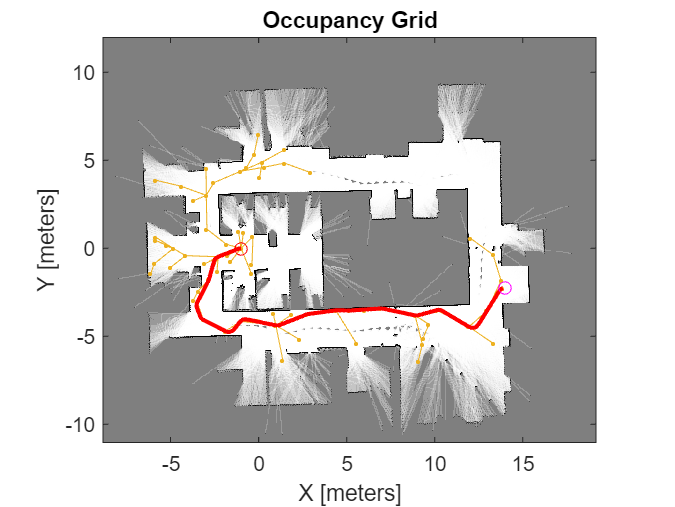

show(occGrid)
hold on

% Plot entire search tree.
plot(solnInfo.TreeData(:,1),solnInfo.TreeData(:,2),'.-');

% Interpolate and plot path.
interpolate(pthObj,300)
plot(pthObj.States(:,1),pthObj.States(:,2),'r-','LineWidth',2)

% Show start and goal in grid map.
plot(start(1),start(2),'ro')
plot(goal(1),goal(2),'mo')
hold off